# **Didacticiel Matlab**

Ce didacticiel aborde la plupart des fonctionnalités utilisées dans les TP de Matlab, notamment pour les TP de Probabilités, Statistiques, Automatique, EDP et Optimisation du semestre 7. 

Vous pouvez exécuter les blocs de texte et de code un par un en allant dans **Run Section **  (ou **Run and Advance**   pour passer à la section suivante) en prenant le temps de bien les comprendre.

# 1) Définition de matrices

Pour définir un **vecteur ligne** :

V_ligne = [1 3 5 7 9]

V_ligne =      1     3     5     7     9


Pour définir un **vecteur colonne** :

V_colonne = [2; 4; 6; 8; 10]

V_colonne =      2
     4
     6
     8
    10


De manière générale, on utilise **des espaces (ou des virgules) comme séparateur horizontal** et le **point virgule comme séparateur vertical**. La même règle s'applique à la définition d'une matrice. Essayez de prédire la matrice qui sera définie par l'instruction suivante avant de l'exécuter :

M = [1 3 5 7 9; 2 4 6 8 10]

M =      1     3     5     7     9
     2     4     6     8    10


On peut également construire `M` à partir de la **concaténation** des vecteurs définis précédemment. On pourrait penser à écrire quelque chose comme :

M = [V_ligne; V_colonne]

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

À l'exécution de cette ligne, une erreur de dimensions est levée. En effet, `V_ligne` est de taille 1x5 et `V_colonne` est de taille 5x1. En transposant `V_colonne` (`V_colonne`**'** ou `transpose(V_colonne)`), on résout ce problème de dimensions :

M = [V_ligne; V_colonne']

Comme les valeurs de `M` sont régulièrement espacées, il est possible d'utiliser des **plages de valeurs** avec un certain pas. Exécutez les deux instructions suivantes et identifiez à chaque fois les bornes de la plage ainsi que le pas.

Enum1 = 3:7:90

Enum2 = 5:3:20

***-------- Exercice*** - Essayez de réécrire `V_ligne`, `V_colonne` et `M` en utilisant des plages.

V_ligne = 1:2:9 % A modifier

V_ligne =      1     3     5     7     9


V_colonne = transpose (2:2:10) % A modifier

V_colonne =      2
     4
     6
     8
    10


M = [1:2:9; 2:2:10] % A modifier

Error using  .' 
Not enough input arguments.

**Attention à ne pas écrire **`V_colonne = 2:2:10'` car la transposition ne s'applique alors qu'à 10 et on obtiendrait un vecteur ligne.

Enfin, il est possible de définir des matrices ne contenant que des 0 ou que des 1, ou encore des matrices identités (des 1 sur la diagonale et des 0 partout ailleurs). Dans tous ces cas, il faut indiquer les dimensions de la matrice souhaitée. Si une seule dimension est donnée, elle est utilisée comme nombre de lignes et de colonnes : on obtient alors une matrice carrée.

M0 = zeros(3,5)

M0 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


M1 = ones(3,5)

M1 =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


M2 = ones(4,4)

M2 =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


M3 = ones(4)

M3 =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


Id = eye(4)

Id =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


# 2) Opérations sur les matrices

Il est possible d'ajouter une constante à un vecteur/une matrice :

MplusTrois = M+3

MplusTrois =      4     6     8    10    12
     5     7     9    11    13


Il est possible de multiplier un vecteur/une matrice par une constante :

troisFoisM = 3*M

troisFoisM =      3     9    15    21    27
     6    12    18    24    30


Il est possible d'additionner des matrices de mêmes tailles

MplusMplusM = M+M+M

MplusMplusM =      3     9    15    21    27
     6    12    18    24    30


Attention, sous certaines conditions, Matlab permet les additions entre une matrice et un vecteur s'ils ont une dimension en commun. Le vecteur est alors répliqué selon la dimension non commune pour faire la même taille que la matrice. Par exemple, les deux instructions suivantes sont équivalentes :

M + [1 3 5 7 9]

ans =      2     6    10    14    18
     3     7    11    15    19


M + [1 3 5 7 9; 1 3 5 7 9]

ans =      2     6    10    14    18
     3     7    11    15    19


`M` est de taille (2,5) et` V_ligne = [1 3 5 7 9]` est de taille (1,5) donc, lors de l'addition, `V_ligne` est répliqué deux fois pour faire la taille de `M`. Il est risqué d'utiliser cette réplication implicite propre à Matlab et nous verrons plus loin comment répliquer manuellement un vecteur ou une matrice.

Le produit matriciel usuel entre une matrice `M1` de taille (m,k) et une autre matrice `M2` de taille (k,n) donne une matrice de taille (m,n). Il se fait comme suit :

M*V_colonne

ans =    190
   220


V_ligne*V_colonne

ans = 190

V_colonne*V_ligne

ans =      2     6    10    14    18
     4    12    20    28    36
     6    18    30    42    54
     8    24    40    56    72
    10    30    50    70    90


Il est alors possible de répliquer un vecteur en le multipliant par un vecteur `ones` de taille adaptée. Par exemple, pour répliquer `[1 3 5 7 9]` de taille (1,5) en `[1 3 5 7 9; 1 3 5 7 9]` de taille (2,5), on peut faire l'instruction suivante :

ones(2,1) * [1 3 5 7 9]

ans =      1     3     5     7     9
     1     3     5     7     9


Enfin, il existe la fonction `repmat` (pour réplique matrice) qui permet de répliquer une matrice un certain nombre de fois horizontalement et/ou verticalement pour obtenir une plus grande matrice. Par exemple :

repmat(M, 4, 2)

ans =      1     3     5     7     9     1     3     5     7     9
     2     4     6     8    10     2     4     6     8    10
     1     3     5     7     9     1     3     5     7     9
     2     4     6     8    10     2     4     6     8    10
     1     3     5     7     9     1     3     5     7     9
     2     4     6     8    10     2     4     6     8    10
     1     3     5     7     9     1     3     5     7     9
     2     4     6     8    10     2     4     6     8    10


Ainsi, pour répliquer `[1 3 5 7 9]` en une matrice de tailles (2,5), on peut faire :

repmat([1 3 5 7 9], 2, 1)

ans =      1     3     5     7     9
     1     3     5     7     9


Il est possible de vectoriser une matrice. Le vecteur obtenu est **la concaténation des colonnes** de la matrice dans une seule et même colonne.

M_vectorise = M(:)

M_vectorise =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


Sur des matrices de mêmes tailles, il est possible d'effectuer des **opérations élément par élément**, comme suit :

I = [200 180 170 190 155; 205 190 195 165 150; 210 215 175 155 190]

I =    200   180   170   190   155
   205   190   195   165   150
   210   215   175   155   190


Coefficients = [0.5 0.2 0.4 0.8 1; 0.4 0.2 0 1 0.9; 0.75 0.5 0.6 1 0.1]

Coefficients =     0.5000    0.2000    0.4000    0.8000    1.0000
    0.4000    0.2000         0    1.0000    0.9000
    0.7500    0.5000    0.6000    1.0000    0.1000


I.*Coefficients % Produit élément par élément de I et de Coefficients

ans =   100.0000   36.0000   68.0000  152.0000  155.0000
   82.0000   38.0000         0  165.0000  135.0000
  157.5000  107.5000  105.0000  155.0000   19.0000


I.*I % Matrice des carrés des éléments de I

ans =        40000       32400       28900       36100       24025
       42025       36100       38025       27225       22500
       44100       46225       30625       24025       36100


I.^3 % Matrice de chaque élément de I élevé à la puissance 3

ans =      8000000     5832000     4913000     6859000     3723875
     8615125     6859000     7414875     4492125     3375000
     9261000     9938375     5359375     3723875     6859000


Certaines fonctions s'effectuent sur tous les éléments d'une matrice sans qu'il soit nécessaire de le préciser avec un ".". C'est notamment le cas des fonctions usuelles cosinus `cos`, sinus `sin`, racine carrée `sqrt`, etc :

racineI = sqrt(I)

racineI =    14.1421   13.4164   13.0384   13.7840   12.4499
   14.3178   13.7840   13.9642   12.8452   12.2474
   14.4914   14.6629   13.2288   12.4499   13.7840


I - racineI.*racineI

ans = 1.0e-13 *

   -0.2842   -0.2842   -0.2842         0         0
         0         0         0         0         0
    0.2842         0         0         0         0


Dans cet exemple, on remarque que l'on obtient pas une matrice entièrement composée de 0 car la précision de la machine sur les opérations flottantes est limitée. Notez la présence du facteur multiplicatif 1.0e-13.

# 3) Modification des éléments d'une matrice

Lorsque l'on veut modifier la valeur d'un élément en particulier, une première syntaxe consiste à préciser le numéro de ligne et le numéro de colonne de l'élément :

Z1 = zeros(7, 5); % Ce point-virgule en fin de ligne permet de ne pas afficher le résultat de l'instruction
Z1(2, 3) = 4

Z1 =      0     0     0     0     0
     0     0     4     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


On remarque qu'en Matlab, les indices commencent à 1 et non à 0 comme dans de nombreux langages (C, Python...). Une deuxième syntaxe consiste à donner **l'indice absolu** de l'élément. De nouveau, on compte selon les colonnes :

Z1(5) = 18

Z1 =      0     0     0     0     0
     0     0     4     0     0
     0     0     0     0     0
     0     0     0     0     0
    18     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


Z1(13) = 21

Z1 =      0     0     0     0     0
     0     0     4     0     0
     0     0     0     0     0
     0     0     0     0     0
    18     0     0     0     0
     0    21     0     0     0
     0     0     0     0     0


Il existe deux fonctions `sub2ind` et `ind2sub` qui permettent de convertir un indice absolu en indices relatifs (numéros de ligne et de colonne) et inversement. Il est nécessaire de donner la taille de la matrice considérée en entrée de ces fonctions :

[ligne, colonne] = ind2sub(size(Z1), 13)

ligne = 6

colonne = 2

indice_absolu = sub2ind(size(Z1), 2, 4)

indice_absolu = 23

La fonction `ind2sub` est une fonction qui peut renvoyer plusieurs sorties : elle renvoie l'indice de ligne et l'indice de colonne. Nous donnerons d'autres exemples de ce genre de fonctions plus loin.

Pour modifier plusieurs éléments simultanément, il faut indiquer les indices des éléments à modifier et donner les nouvelles valeurs de ces éléments dans une matrice de taille adaptée. Nous donnons plusieurs exemples ci-dessous, prenez le temps de les comprendre :

Z2 = zeros(9, 7);
Z2(2, 3:7) = V_ligne

Z2 =      0     0     0     0     0     0     0
     0     0     1     3     5     7     9
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


Z2(4:8, 1) = V_colonne

Z2 =      0     0     0     0     0     0     0
     0     0     1     3     5     7     9
     0     0     0     0     0     0     0
     2     0     0     0     0     0     0
     4     0     0     0     0     0     0
     6     0     0     0     0     0     0
     8     0     0     0     0     0     0
    10     0     0     0     0     0     0
     0     0     0     0     0     0     0


Z2(5:6, 3:7) = M

Z2 =      0     0     0     0     0     0     0
     0     0     1     3     5     7     9
     0     0     0     0     0     0     0
     2     0     0     0     0     0     0
     4     0     1     3     5     7     9
     6     0     2     4     6     8    10
     8     0     0     0     0     0     0
    10     0     0     0     0     0     0
     0     0     0     0     0     0     0


Il est possible d'extraire une sous-matrice en indiquant les plages d'indices désirées. Par exemple :

Z2(3:8, 1:5)

ans =      0     0     0     0     0
     2     0     0     0     0
     4     0     1     3     5
     6     0     2     4     6
     8     0     0     0     0
    10     0     0     0     0


On peut également indiquer un pas. Essayez de prédire ce que renvoie l'instruction suivante puis exécutez-la :

Z2(2:2:6, 3:2:7)

ans =      1     5     9
     0     0     0
     2     6    10


La sous-matrice obtenue est de taille (3,3). Il est donc possible de modifier tous ces éléments d'un coup en donnant les nouvelles valeurs dans une matrice de taille (3,3), comme dans l'exemple suivant. Prenez le temps de bien localiser les éléments de `A` dans la matrice `Z2` :

A = [3 4 2; 5 5 5; 9 0 3]

A =      3     4     2
     5     5     5
     9     0     3


Z2(2:2:6, 3:2:7) = A

Z2 =      0     0     0     0     0     0     0
     0     0     3     3     4     7     2
     0     0     0     0     0     0     0
     2     0     5     0     5     0     5
     4     0     1     3     5     7     9
     6     0     9     4     0     8     3
     8     0     0     0     0     0     0
    10     0     0     0     0     0     0
     0     0     0     0     0     0     0


La longueur d'un vecteur peut être obtenue par la fonction `length` :

longueur = length(V_ligne)

longueur = 5

L'utilisation de `length` sur une matrice est déconseillé car la fonction ne retourne alors que la plus grande dimension de la matrice. Le **nombre de lignes** et le **nombre de colonnes** d'une matrice peuvent être obtenus avec `size` en faisant :

Z3 = zeros(6, 4)

Z3 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


nb_lignes = size(Z3, 1)

nb_lignes = 6

nb_colonnes = size(Z3, 2)

nb_colonnes = 4

[nb_lignes,nb_colonnes] = size(Z3)

nb_lignes = 6

nb_colonnes = 4

plus_grande_dimension = length(Z3)

plus_grande_dimension = 6

Il existe plusieurs façons de redéfinir une ligne (ou une colonne) entière. On peut donner une plage d'indices allant de 1 à `nb_lignes` ou `nb_colonnes` :

Z3(4, 1:nb_colonnes) = 99

Z3 =      0     0     0     0
     0     0     0     0
     0     0     0     0
    99    99    99    99
     0     0     0     0
     0     0     0     0


Z3(1:nb_lignes, 2) = -55

Z3 =      0   -55     0     0
     0   -55     0     0
     0   -55     0     0
    99   -55    99    99
     0   -55     0     0
     0   -55     0     0


On peut utiliser le symbole "`:`" qui indique de considérer tous les éléments de la ligne (ou de la colonne) :

Z4 = zeros(6, 4)

Z4 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Z4(3, :) = 11

Z4 =      0     0     0     0
     0     0     0     0
    11    11    11    11
     0     0     0     0
     0     0     0     0
     0     0     0     0


Z4(:, 4) = -33

Z4 =      0     0     0   -33
     0     0     0   -33
    11    11    11   -33
     0     0     0   -33
     0     0     0   -33
     0     0     0   -33


Enfin, il est possible d'utiliser le mot clé `end` à la place de `nb_lignes` ou `nb_colonnes` pour aller au bout d'une dimension :

Z5 = zeros(6, 4)

Z5 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Z5(2, 1:end) = 222

Z5 =      0     0     0     0
   222   222   222   222
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Z5(1:end, 1) = 666

Z5 =    666     0     0     0
   666   222   222   222
   666     0     0     0
   666     0     0     0
   666     0     0     0
   666     0     0     0


Pour modifier simultanément plusieurs éléments, on utilise un vecteur d'indices absolus. Par exemple, pour mettre la valeur 1 aux indices absolus `2, 5, 7, 12, 13, 14, 19` d'une matrice de taille (6,4), on utilise :

Z6 = zeros(6, 4)

Z6 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Z6([2, 5, 7, 12, 13, 14, 19]) = 1

Z6 =      0     1     1     1
     1     0     1     0
     0     0     0     0
     0     0     0     0
     1     0     0     0
     0     1     0     0


La fonction `sub2ind` évoquée précédemment peut s'avérer utile pour récupérer un indice absolu à partir des numéros de ligne et de colonne d'un élément. En pratique, on n'utilise rarement ces conversions car Matlab dispose de fonctions qui permettent de s'en passer. Nous donnons un exemple ci-dessous.

Supposons que l'on dispose d'une matrice I et que l'on souhaite remplacer tous les éléments de `I` de valeur inférieure à un certain seuil (disons 177) par 0. L'instruction `I <= 177` renvoie une matrice booléenne :

I = [200 180 170 190 155; 205 190 195 165 150; 210 215 175 155 190]

I =    200   180   170   190   155
   205   190   195   165   150
   210   215   175   155   190


I <= 177

ans = 3×5 logical array
   0   0   1   0   1
   0   0   0   1   1
   0   0   1   1   0


Pour récupérer les indices des valeurs de `I` inférieures à 177 avec `find` :

find(I <= 177)

ans =      7
     9
    11
    12
    13
    14


On peut alors récupérer les éléments de `I` inférieurs à 177 en faisant :

I(find(I <= 177))

ans =    170
   175
   165
   155
   155
   150


L'instruction suivante, plus épurée et optimale (d'où le surlignage orange ci-dessus pour un avertissement d'optimalité du code), renvoie le même résultat :

I(I <= 177)

ans =    170
   175
   165
   155
   155
   150


Ainsi, pour mettre à 0 tous les éléments de I inférieures à 177, on peut écrire :

I(I <= 177) = 0

I =    200   180     0   190     0
   205   190   195     0     0
   210   215     0     0   190


Enfin, pour tester l'égalité entre deux matrices (ou vecteurs), on pourrait être tentés de faire :

A = [pi, 2*pi, 3*pi; 4*pi, 5*pi, 6*pi] 

A =     3.1416    6.2832    9.4248
   12.5664   15.7080   18.8496


B = [3.1416, 6.2832, 9.4248; 12.5664, 15.7080, 18.8496]

B =     3.1416    6.2832    9.4248
   12.5664   15.7080   18.8496


(A == B)

ans = 2×3 logical array
   0   0   0
   0   0   0


Les valeurs affichées dans `A` et dans `B` sont les mêmes. Pourtant, la matrice de booléens `A == B` ne contient que des 0 (associés à la valeur "faux"). Deux problèmes entrent en jeu :

- d'une part, Matlab n'affiche qu'un certain nombre de décimales ;

- d'autre part, lorsque l'on manipule des nombres flottants, on manipule en vérité des valeurs à une précision machine près.

La façon standard de vérifier que deux flottants sont égaux consiste donc à vérifier que leur différence en valeur absolue est inférieur à un certain seuil de précision fixé par l'utilisateur en fonction du contexte. Par exemple :

abs(pi-3.1416) < 0.001

ans = logical
   1


abs(pi-3.1416) < 0.000001

ans = logical
   0


De façon analogue, la vérification d'égalité entre deux matrices impliquera :

- de vérifier qu'elles ont la même taille (donc le même nombre de coefficients) ;

- que les différences en valeur absolue des coefficients terme à terme sont inférieures à un certain seuil.

# 4) Fonctions utiles

On peut modifier la forme d'une matrice avec la fonction `reshape` : la seule contrainte est que le nombre d'éléments total doit rester le même. À nouveau, l'ordre des éléments se retrouve dans la vectorisation de la matrice, comme illustré ci-dessous sur une matrice de taille (4,6) (donc à 24 éléments). Prenez le temps de bien comprendre les exemples ci-dessous :

J = [200 180 170 190 155 120; 205 190 195 165 150 60; 210 215 175 155 190 160; 125 155 165 145 200 185]

J =    200   180   170   190   155   120
   205   190   195   165   150    60
   210   215   175   155   190   160
   125   155   165   145   200   185


J1 = J(:) % Vectorisation de J

J1 =    200
   205
   210
   125
   180
   190
   215
   155
   170
   195


J2 = reshape(J, 3, 8)

J2 =    200   125   215   195   190   145   190    60
   205   180   155   175   165   155   200   160
   210   190   170   165   155   150   120   185


J3 = reshape(J, 6, 4)

J3 =    200   215   190   190
   205   155   165   200
   210   170   155   120
   125   195   145    60
   180   175   155   160
   190   165   150   185


J4 = reshape(J, 8, 3)

J4 =    200   170   155
   205   195   150
   210   175   190
   125   165   200
   180   190   120
   190   165    60
   215   155   160
   155   145   185


J5 = reshape(J, 24, 1) % équivalent à J(:)

J5 =    200
   205
   210
   125
   180
   190
   215
   155
   170
   195


La fonction `max` permet de récupérer l'élément d'un vecteur (colonne ou ligne) de valeur maximale, ainsi que son indice. Il s'agit d'une fonction qui peut renvoyer plusieurs sorties, tout comme `size`. Observez les deux syntaxes suivantes et identifiez les différences :

W = [4, 12, 3, 7, 6]

W =      4    12     3     7     6


valeur_maximale = max(W)

valeur_maximale = 12

[valeur_maximale, indice_du_maximum] = max(W)

valeur_maximale = 12

indice_du_maximum = 2

Si l'on ne précise qu'une seule sortie, `max` ne renvoie que la valeur maximale. Pour obtenir l'indice du maximum, il faut demander deux sorties entre crochets comme dans la deuxième syntaxe. Si l'on ne souhaite se servir que de l'indice du maximum, il est possible de se passer de la sortie correspondant à la valeur du maximum (la première donc) avec le symbole "`~`" :

[~, indice_du_maximum] = max(W)

indice_du_maximum = 2

Dans le cas d'une matrice, la fonction `max` permet de récupérer la valeur maximale de chaque colonne ainsi que son indice.

J

J =    200   180   170   190   155   120
   205   190   195   165   150    60
   210   215   175   155   190   160
   125   155   165   145   200   185


maxima = max(J)

maxima =    210   215   195   190   200   185


[~, indices_maxima] = max(J)

indices_maxima =      3     3     2     1     4     4


Si l'on souhaite récupérer les maxima (ou les indices) transpose (de chaque ligne et non plus de chaque colonne, il faut préciser la dimension à la fonction **max** de la manière suivante :

J

J =    200   180   170   190   155   120
   205   190   195   165   150    60
   210   215   175   155   190   160
   125   155   165   145   200   185


maxima = max(J,[],2)

maxima =    200
   205
   215
   200


[~, indices_maxima] = max(J,[],2)

indices_maxima =      1
     1
     2
     5


De la même façon, la fonction `sort` permet de trier les valeurs par ordre croissant ('ascend') ou décroissant ('descend') et de renvoyer les indices correspondants si deux sorties sont demandées.

valeurs_ordre_croissant = sort(W, 'ascend') % L'ordre est croissant par défaut si l'on ne précise pas dans la fonction

valeurs_ordre_croissant =      3     4     6     7    12


valeurs_ordre_decroissant = sort(W, 'descend')

valeurs_ordre_decroissant =     12     7     6     4     3


[valeurs_ordre_croissant, indices_ordre_croissant] = sort(W, 'ascend')

valeurs_ordre_croissant =      3     4     6     7    12


indices_ordre_croissant =      3     1     5     4     2


[~, indices_ordre_croissant] = sort(W, 'ascend')

indices_ordre_croissant =      3     1     5     4     2


On peut vérifier que `W(indices_ordre_croissant)` donne `valeurs_ordre_croissant` :

W(indices_ordre_croissant)

ans =      3     4     6     7    12


valeurs_ordre_croissant

valeurs_ordre_croissant =      3     4     6     7    12


La fonction `mean` renvoie :

- la moyenne des éléments d'un vecteur lorsqu'elle est utilisée sur un vecteur ;

- les moyennes de chaque colonne ou de chaque ligne d'une matrice lorsqu'elle est utilisée sur une matrice.

Pour préciser si la moyenne doit être calculée par lignes ou par colonnes, il est nécessaire d'ajouter un deuxième argument égal à 1 (par colonnes) ou à 2 (par lignes). Par défaut, en l'absence de deuxième argument, la moyenne est calculée par colonnes (valeur par défaut : 1).

V = [2 3 5 8 12]

V =      2     3     5     8    12


mean(V)

ans = 6

M = [1 3 5 7 9; 2 4 6 8 10]

M =      1     3     5     7     9
     2     4     6     8    10


moyennes_par_colonnes = mean(M, 1)

moyennes_par_colonnes =     1.5000    3.5000    5.5000    7.5000    9.5000


moyennes_par_lignes = mean(M, 2)

moyennes_par_lignes =      5
     6


moyennes_par_defaut = mean(M)

moyennes_par_defaut =     1.5000    3.5000    5.5000    7.5000    9.5000


De façon similaire, la fonction `sum` renvoie :

- la somme des éléments d'un vecteur lorsqu'elle est utilisée sur un vecteur ;

- les sommes de chaque colonne ou de chaque ligne d'une matrice lorsqu'elle est utilisée sur une matrice. De nouveau, pour préciser si les moyennes doivent être calculées par lignes ou par colonnes, on ajoute un deuxième argument égal à 1 (par colonnes) ou à 2 (par lignes). Par défaut, si l'on n'indique pas de deuxième argument, il est égal à 1.

V = [2 3 5 8 12]

V =      2     3     5     8    12


sum(V)

ans = 30

M = [1 3 5 7 9; 2 4 6 8 10]

M =      1     3     5     7     9
     2     4     6     8    10


sommes_par_colonnes = sum(M, 1)

sommes_par_colonnes =      3     7    11    15    19


sommes_par_lignes = sum(M, 2)

sommes_par_lignes =     25
    30


sommes_par_defaut = sum(M)

sommes_par_defaut =      3     7    11    15    19


Ainsi, les moyennes peuvent être calculées soit avec `mean`, soit avec `sum` et `size`.

M = [1 3 5 7 9; 2 4 6 8 10];
mean(M, 1)

ans =     1.5000    3.5000    5.5000    7.5000    9.5000


sum(M, 1)/size(M, 1)

ans =     1.5000    3.5000    5.5000    7.5000    9.5000


mean(M, 2)

ans =      5
     6


sum(M, 2)/size(M, 2)

ans =      5
     6


Enfin, il est possible de consulter la document d'une fonction avec la commande `help` ou en tapant dans *Search Documentation *situé en haut à droite dans Matlab. Des exemples numériques sont notamment donnés en fin de documentation :

help sum

 sum - Sum of array elements
    This MATLAB function returns the sum of the elements of A along the
    first array dimension whose size is greater than 1.

    Syntax
      S = sum(A)
      S = sum(A,"all")
      S = sum(A,dim)
      S = sum(A,vecdim)
      S = sum(___,outtype)
      S = sum(___,nanflag)

    Input Arguments
      A - Input array
        vector | matrix | multidimensional array | table | timetable
      dim - Dimension to operate along
        positive integer scalar
      vecdim - Vector of dimensions
        vector of positive integers
      <a href="matlab

# 5) Définir une fonction

Il est possible de définir des fonctions en donnant ses paramètres d'entrée et de sortie. L'idée est avant tout de voir la syntaxe d'une défintion de fonction. Pour ce faire, chaque fonction Matlab est écrite dans un fichier à part portant le nom de la fonction en question.

Par exemple, si l'on veut définir une fonction appelée `calculs_basiques` qui, à partir de deux entrées `a` et `b` renvoie trois sorties contenant respectivement la somme, la différence et le produit de `a` et `b`, on ouvre le finchier `calculs_basiques.m `contenant le prototype de la fonction en question.

resultats = calculs_basiques(3, 5)

resultats = 8

`resultats` sera égal à 8 car il ne contiendra que la première sortie de `calculs_basiques` (somme). On a déjà abordé ce point en présentant les fonctions `sort` et `max` : elles peuvent retourner plusieurs sorties mais ne retournent que la première d'entre elles si l'on ne précise pas avec des crochets les sorties désirées.

Si maintenant à l'inverse on crée une fonction `calculs_basiques_variante` (voir fichier de fonction du même nom) qui renvoie les 3 calculs sous forme de vecteur dans une seule variable de sortie, une erreur sera affichée par la ligne suivante car une seule sortie est attendue de la part de cette fonction.

[somme, difference, produit] = calculs_basiques_variante(3, 5);

Error using calculs_basiques_variante
Too many output arguments.

# 6) Les structures de contrôle

### 6.1) Les boucles for

Lorsque l'on veut faire une boucle `for` en Matlab, on précise un vecteur contenant toutes les valeurs que doit prendre l'indice de boucle (i dans l'exemple donné ci-dessous). Par exemple, pour une boucle de 1 à 1000 on utilisera le vecteur [1 2 3 ... 1000] qui s'écrit plus simplement `1:1000`.

somme = 0;
for i = 1:5
    somme = somme + i  % Ajouter un ';' en fin de ligne permet d'éviter l'affichage 
end

somme = 1

somme = 3

somme = 6

somme = 10

somme = 15

Cet exemple illustre bien l'intérêt d'ajouter des "`;`" en fin de ligne pour éviter l'affichage.

Dans l'exemple suivant, nous souhaitons calculer une matrice C qui est la somme de deux matrices A et B. Nous montrons comment le faire de deux manières différentes :

- avec une boucle `for`

- matriciellement

Pour chaque méthode, nous mesurons le temps d'exécution en appelant les instructions `tic` et `toc` respectivement avant et après le bloc de code dont on veut mesurer le temps d'exécution.

A = rand(2000,1500);
B = rand(size(A));
C = zeros(size(A));

tic
% Avec une boucle for
for i = 1:size(C, 1)
    for j = 1:size(C, 2)
        C(i, j) = A(i, j) + B(i, j);
    end
end
toc

Elapsed time is 0.123548 seconds.


A = rand(2000, 1500);
B = rand(size(A));

tic
C = A + B;
toc

Elapsed time is 0.011630 seconds.


Bien souvent, le fait d'utiliser des boucles `for` augmente les temps de calcul. Il n'est cependant pas toujours évident de se passer de ces boucles, mais nous vous demanderons de les éviter au maximum lorsqu'elles sont remplaçables par d'autres fonctions ou opérations matricielles.

Pour illustrer un cas où se passer de boucle `for` n'est pas évident, nous proposons l'exemple d'une quantification d'histogramme. Nous souhaitons compter le nombre d'éléments d'une matrice dont la valeur est comprise entre 0 et 0.1, entre 0.1 et 0.2, entre 0.2 et 0.3...et entre 0.9 et 1. De nouveau, nous proposons une version avec boucle `for` et une version sans. Prenez le temps de bien comprendre les deux versions :

M = rand(800, 600);

Histogramme = zeros(1, 10);

tic
for i = 1:size(M, 1)
    for j = 1:size(M, 2)
        valeur = floor(M(i, j)*10);  % pour obtenir un indice entre 0 et 9
        indice = valeur+1;  % les indices en Matlab commencent à 1
        Histogramme(indice) = Histogramme(indice) + 1;
    end
end
toc

Elapsed time is 0.023298 seconds.


M = rand(800, 600);

tic
M = repmat(M(:), 1, 10);
intervalles1 = 0:0.1:0.9;
intervalles2 = 0.1:0.1:1;

% Pas besoin d'initialiser Histogramme car la variable est remplie en une fois
Histogramme = sum(M >= intervalles1 & M < intervalles2); 
tocq

Elapsed time is 0.034352 seconds.


Le symbole `&` désigne ici le ET logique. De la même façon, on peut écrire un OU logique avec le symbole `|`. Dupliquer les matrices ou vecteurs pour éviter les boucles finit par avoir ses limites en temps avec l'augmentation des calculs.

### 6.2) Utilisation de while et if

Nous illustrons rapidement l'utilisation de `while` et `if` pour chercher à déterminer si un nombre `n` est premier ou non en calculant le reste de la division euclidienne de tous les nombres de 2 à racine carrée (`sqrt`) de `n` et en déclarant que le nombre n'est pas premier si l'un de ces restes est nul. En Matlab, on peut écrire :

n=983;

primalite = 1;
indice = 2;
while indice <= sqrt(n) && primalite
    if mod(n, indice) == 0
        primalite = 0;
    end
    indice = indice + 1;
end

primalite

primalite = 1

Au même titre que le test d'égalité se faisait avec "`==`" (2 fois le symbole), les tests pour les ET et OU logiques suivent la même règle : "`&&`" et "`||`".

# 7) Affichage de courbes

### 7.1) Plot de **ℝ **dans **ℝ **

Il est possible de tracer des courbes avec la fonction `plot`. Commençons par un exemple simple :

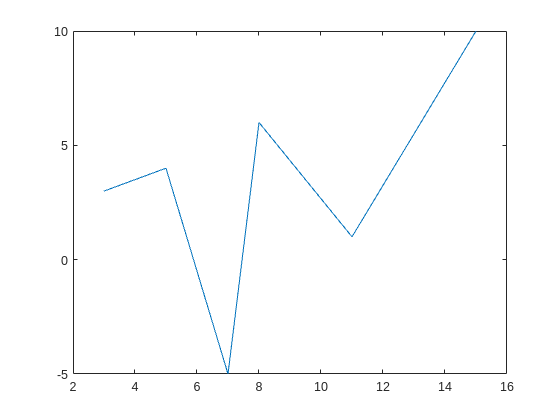

X = [3, 5, 7, 8, 11, 15];
Y = [3, 4, -5, 6, 1, 10];
plot(X, Y);

Pour ajouter un titre à la figure, on peut faire :

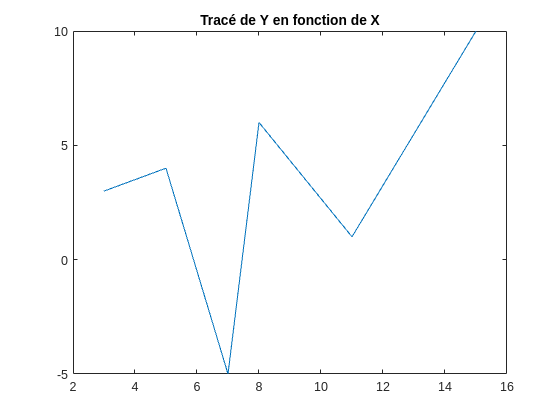

plot(X, Y);
title('Tracé de Y en fonction de X');

On peut également ajouter du texte le long des axes :

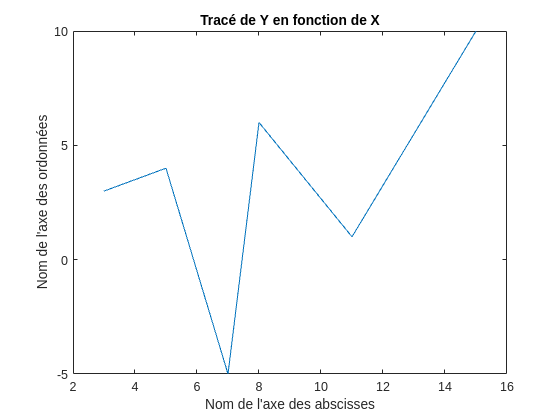

plot(X, Y);
title('Tracé de Y en fonction de X');
xlabel('Nom de l''axe des abscisses');
ylabel('Nom de l''axe des ordonnées');

Mais aussi des légendes dans le cas où plusieurs courbes sont superposées sur le même graphique : 

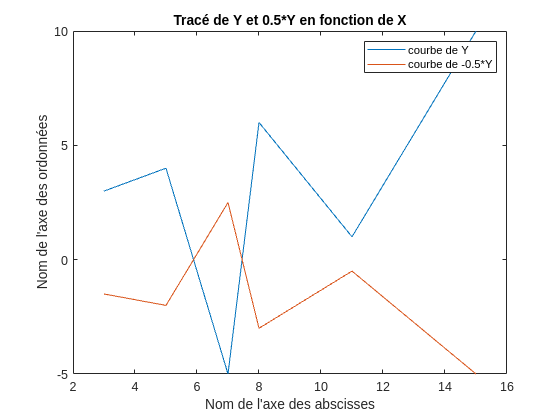

plot(X, Y);
hold on
plot(X, -0.5*Y)
hold off
title('Tracé de Y et 0.5*Y en fonction de X');
xlabel('Nom de l''axe des abscisses');
ylabel('Nom de l''axe des ordonnées');
legend('courbe de Y','courbe de -0.5*Y')

On peut préciser la couleur du tracé et aussi si l'on veut des symboles simplement sans relier les points  :

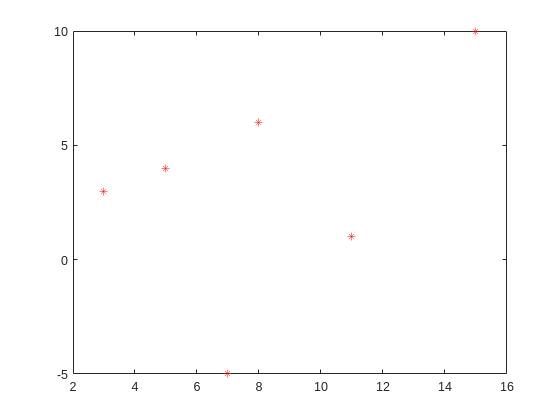

plot(X, Y,'r*');

On peut regrouper plusieurs figures avec la fonction `subplot` : on indique d'abord le nombre de lignes `n`, le nombre de colonnes `m` et enfin l'indice (entre 1 et n*m) de la figure que l'on dessine. On peut choisir pour chaque sous-figure d'ajouter un titre et des étiquettes sur les axes ou non :

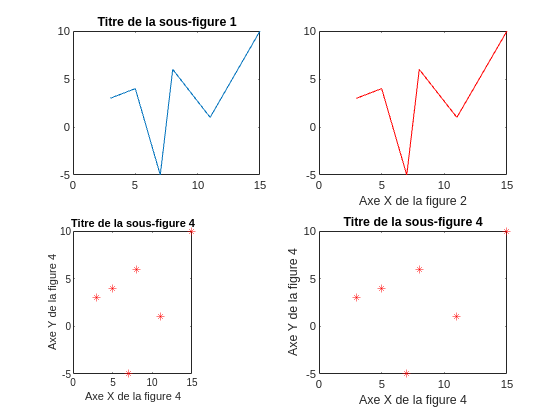

subplot(2,2,1);
plot(X, Y);
title('Titre de la sous-figure 1')

subplot(2,2,2);
plot(X, Y,'r');
xlabel('Axe X de la figure 2')

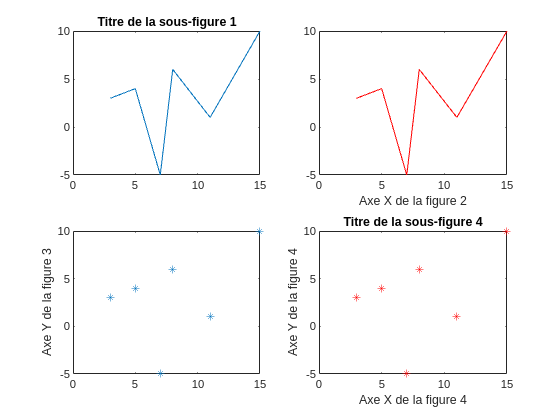


subplot(2,2,3);
plot(X, Y,'*');
ylabel('Axe Y de la figure 3')

subplot(2,2,4);
plot(X, Y,'r*');
title('Titre de la sous-figure 4')
xlabel('Axe X de la figure 4')
ylabel('Axe Y de la figure 4')

### 7.2) plot de **ℝ**² dans **ℝ**

La fonction `contour(X,Y,Z)` permet un affichage en lignes de niveaux. De nouveau, nous illustrons son utilisation au travers d'un exemple. Nous commençons par définir deux axes `X` et `Y` gradués à chaque unité de -20 à 20 : `X` et `Y` sont donc deux vecteurs de taille 41. Une valeur z est attribuée à chaque couple (x, y). Pour pouvoir utiliser `contour`, il faut stocker tous les valeurs z dans une matrice `Z` (qui seront donc de taille 41x41).

Pour avoir une certaine régularité dans les lignes de niveaux de l'exemple ci-dessous, nous calculons chaque valeur de `Z` à partir des valeurs voisines et perturbons la valeur d'une quantité comprise entre -0.5 et 0.5 (`rand`-0.5). Il aurait été possible de simplement assigner une valeur aléatoire, mais les lignes de niveaux auraient alors été plus difficiles à visualiser.

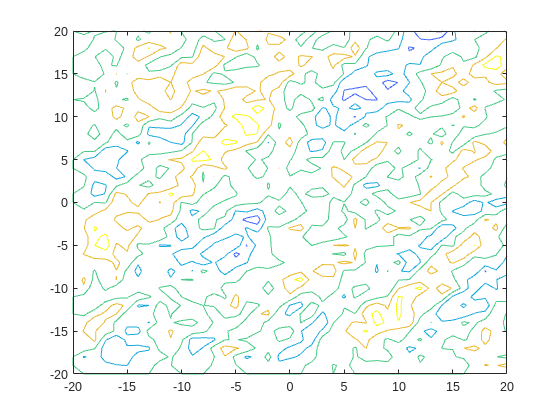

close all % Pour fermer le subplot

X = -20:20;
Y = -20:20;
Z = zeros(41,41);
for i = 2:41
    for j = 2:41
        Z(i,j) = rand - 0.5 + (Z(i-1,j-1)+Z(i-1,j)+Z(i,j-1))/3;
    end
end
contour(X, Y, Z);

Enfin, la documentation Matlab détaille et illustre tous les types d'affichage possibles (on y retrouve notamment des histogrammes et des courbes en 3D) sur la page suivante : [https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html.](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html.)

# 8) Lecture et affichage d'images

En Matlab, les images sont représentées par des matrices dont chaque élément représente le niveau de gris (pour des images en noir et blanc) ou la couleur (pour des images en couleur) d'un pixel de l'image. Pour des images en niveaux de gris, les matrices associées sont bidimensionnelles et sont de taille (`nb_lignes, nb_colonnes`). Pour des images en couleur, les matrices associées sont tridimensionnelles et sont de taille (`nb_lignes, nb_colonnes, 3`) : les 3 canaux de la troisième dimension permettent d'encoder le niveau de couleur (rouge, vert ou bleu) du pixel (codage RGB).

Les valeurs sont prises entre 0 et 255 inclus.

À titre d'exemples :

- (r = 255, g = 0, b = 0) donne du rouge vif

- (r = 255, g = 255, b = 0) donne du jaune vif

- (r = 128, g = 128, b = 128) donne du gris

- pour des images en niveaux de gris, 0 correspond au noir et 255 au blanc

Vous pouvez sélectionner une couleur et obtenir son code RGB sur le site suivant : [https://htmlcolorcodes.com/fr/selecteur-de-couleur/](https://htmlcolorcodes.com/fr/selecteur-de-couleur/)

De manière générale, les fonctions d'affichage seront déjà écrites dans les TP de probabilités et statistiques. Nous présentons donc rapidement les principales fonctions.

Matlab dispose de quelques images internes. La lecture d'une image se fait avec la fonction `imread` :

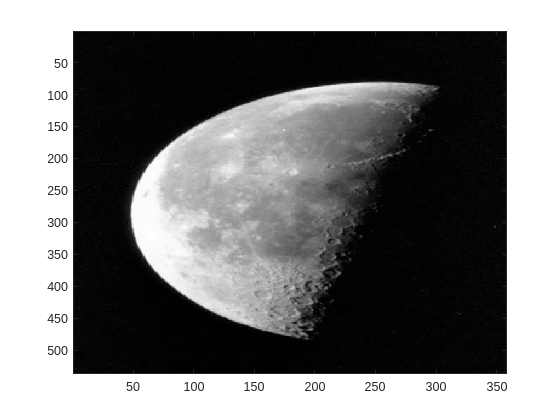

I = imread('moon.tif');
imagesc(I);

Pour l'affichage des images en niveaux de gris, Matlab utilise une palette de couleurs. Par défaut, il s'agit de couleurs allant du jaune/vert pour les niveaux de gris élevés au bleu pour les niveaux de gris faibles. Il est possible de modifier la palette de couleurs avec l'instruction `colormap` comme suit :

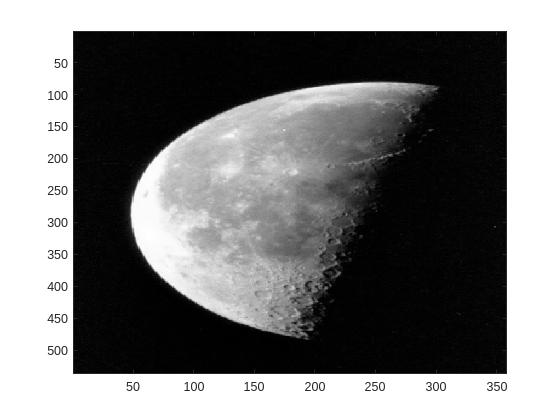

imagesc(I)
colormap gray;

Il se peut que les proportions ne soient pas bien conservées lors de l'affichage, c'est pourquoi il faut agir sur les axes avec l'instruction `axis` (pour conserver le ratio et aussi enlever les nombres sur les axes) :

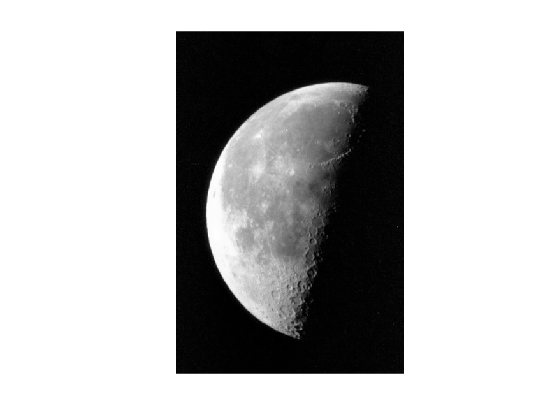

imagesc(I)
colormap gray;
axis equal off; % axis image est presque équivalent à axis equal

Ci-dessous, un exemple d'image en couleur. Notez que la matrice est affichée canal par canal : `I(:,:,1)` correspond au canal rouge, `I(:,:,2)` au canal vert et `I(:,:,3)` au canal bleu par convention. Lorsque l'on affiche des images en couleur, il n'y a pas de colormap à gérer.

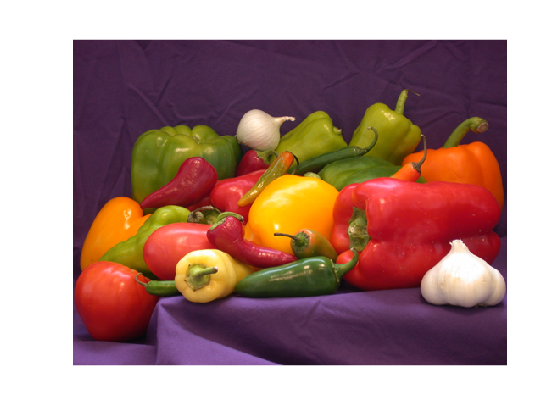

I = imread('peppers.png');  % ";" pour ne pas afficher la matrice en sortie
imagesc(I);
axis image off;

# 9) Exercice applicatif

Le script suivant lit une image en niveaux de gris, la stocke dans la matrice bidimensionnelle `image_originale` et l’affiche. 

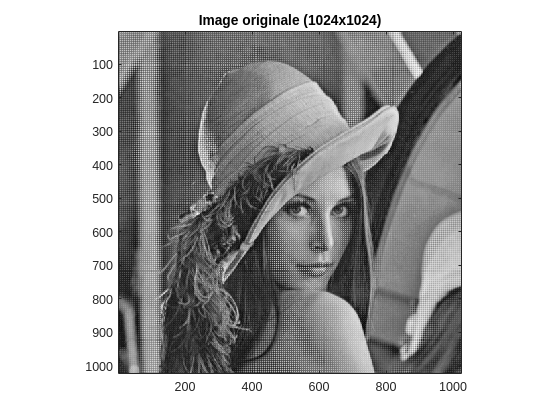

% Lecture et affichage de l'image originale :
image_originale = imread('image_originale.png');
imagesc(image_originale);
axis image;
colormap gray;
title('Image originale (1024x1024)')

Les niveaux de gris des pixels de cette image sont obtenus après traversée d’une mosaïque de filtres colorés, appelée matrice de Bayer (voir ci-dessous), qui est placée devant le récepteur photosensible des appareils photographiques.

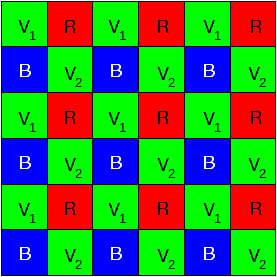

Matrice de Bayer

Ecrivez la fonction `ecriture_RVB `dans le fichier **ecriture_RVB.m** que vous devez au préalable créer. L’en-tête de cette fonction s’écrit :

`function image_RVB = ecriture_RVB(image_originale)`

Elle doit créer une matrice `image_RVB` à 3 dimensions contenant deux fois moins de lignes et deux fois moins de colonnes que `image_originale`. Chaque pixel de `image_RVB` correspond à un ensemble de quatre pixels de `image_originale` : `V1`, `R`, `V2`, `B`. Les valeurs `R` et `B` sont recopiées telles quelles dans les canaux rouge et bleu de `image_RVB`. En revanche, la valeur dans le canal vert est égale à la moyenne des valeurs `V1` et `V2`. Pour concaténer des matrices suivant la 3ème dimension, on pourra utiliser la fonction `cat(3,canal_R,canal_V,canal_B)`. Une fois la fonction terminée, lancez le script suivant pour vérifier le résultat.

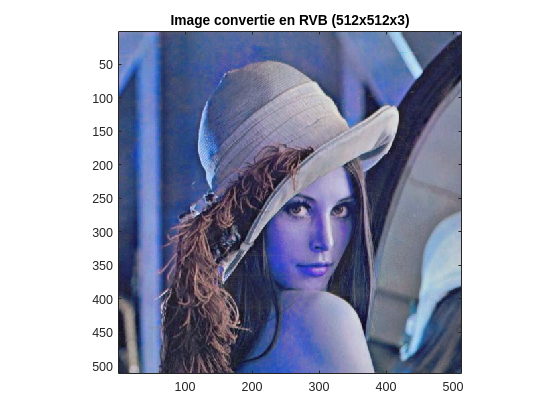

% Conversion des entiers non signés en doubles :
image_originale = double(image_originale);

% Ecriture de image_RVB :
image_RVB = ecriture_RVB(image_originale);

% Affichage de l'image RVB convertie en entiers non signes :
imagesc(uint8(image_RVB));
axis image;
title('Image convertie en RVB (512x512x3)')

On voit bien que les dimensions de l'image ont été divisées par 2. On remarquera que l'on a passé l'image en type double pour faire des opérations à virgule pour le canal vert, puisque la plupart du temps les images sont codées en entiers non signés sur 8 bits (valeurs entre 0 et 255). On repasse l'image dans ce format avant de faire l'affichage final.

# 10) Erreurs classiques

On parvient rarement à écrire un code sans erreur du premier coup. Au travers de messages d'erreur, Matlab indique généralement le type d'erreur rencontré (problème de dimension, variable non définie...) et la ligne à laquelle se produit l'erreur.

Dans cette partie, nous vous fournissons plusieurs instructions Matlab qui renvoient une erreur lorsqu'elles sont lancées. À vous de comprendre d'où proviennent les erreurs et de les corriger.

**Il faut enlever le symbole "**`%`**" en début de ligne pour décommenter le code.**

A- On souhaite créer une matrice de taille 320 x 240 avec des nombres aléatoires compris entre 0 et 256

% Matrice = 256*rand(320, 240));

Vous remarquerez dans la petite barre de droite un tiret orange pour signaler un warning et un tiret rouge pour signaler une erreur. Lorsque que vous avez décommenté, un tiret rouge est apparu. 

**S'il y a une erreur dans n'importe quelle partie d'un fichier, toutes les lignes de codes présentes dans le fichier ne fonctionneront pas** (cela est dû à l'erreur qui arrête la compilation du fichier).

B- On souhaite ajouter à chaque colonne de A sa colonne suivante. La dernière colonne de A reste inchangée.

% Matrice(:, 1:end-1) = Matrice(:, 1:end-1) + matrice(:, 1:end);

C- On souhaite ensuite centrer les valeurs en retirant la valeur moyenne de la matrice obtenue.

% Matrice = Matrice - repmat(mean(meen(Matrice)), 320, 240);

D- On souhaite mettre à 0 tous les coefficients négatifs de la matrice.

% (Matrice < 0) = 0;